# Predict House Prices Using Deep Learning and Machine Learning

Kevin Chng, AE, TechSource

## Overview :

This is a very interesting exploration, I'm going to explore how to utilize different approaches (Deep Learning, Machine Learning, or combination of both technique) to predict house price. Here, I will train 2 types of prediction which are classification (very cheap,cheap, normal, expensive, very expensive) and regression (House Price) . The accuracy might still not optimistic due to insufficient data or information, however, it is interesting to see how to use different approaches to predict house price.

Let me know, if you have better solution, then we can enrich our solution.

**Classification Prediction :**

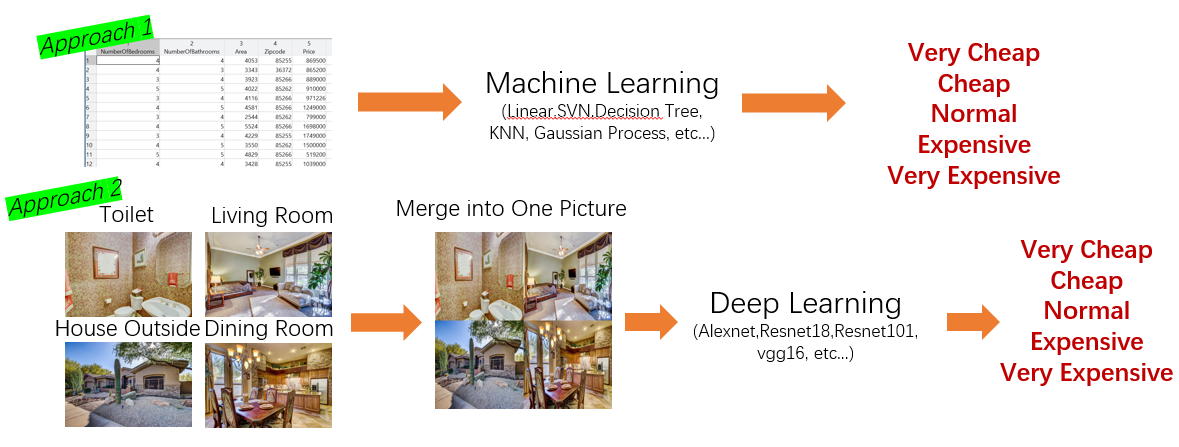

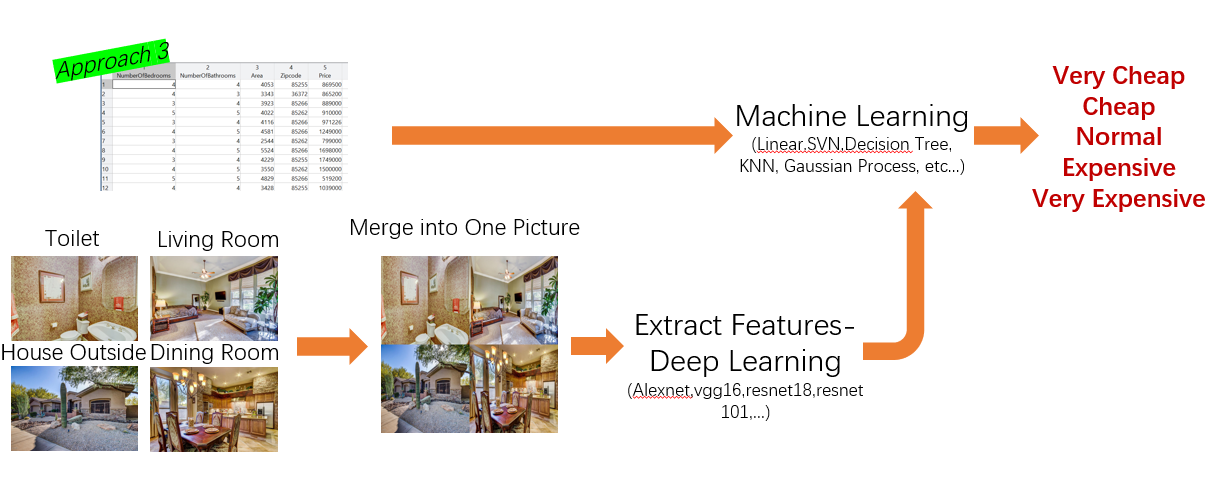

**Regression Prediction : **

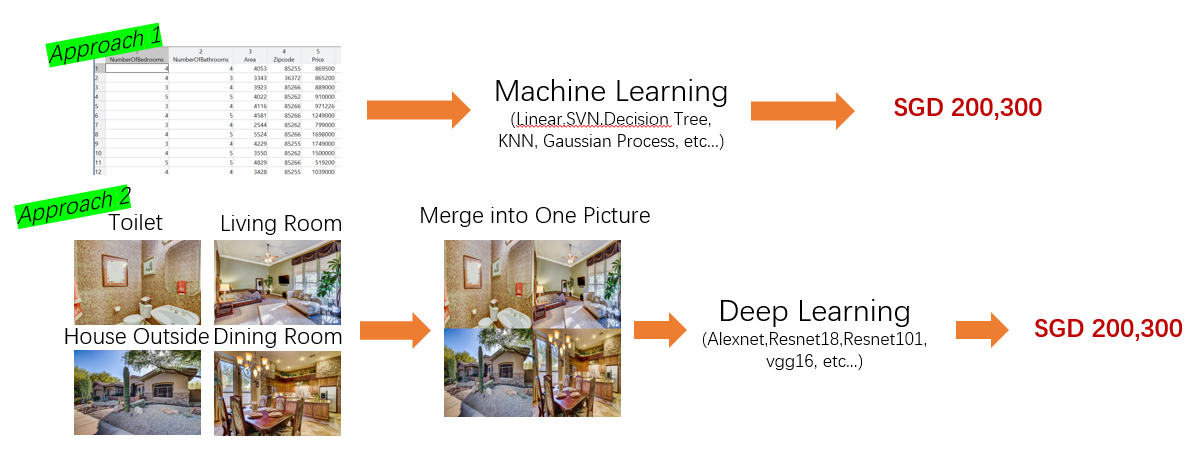

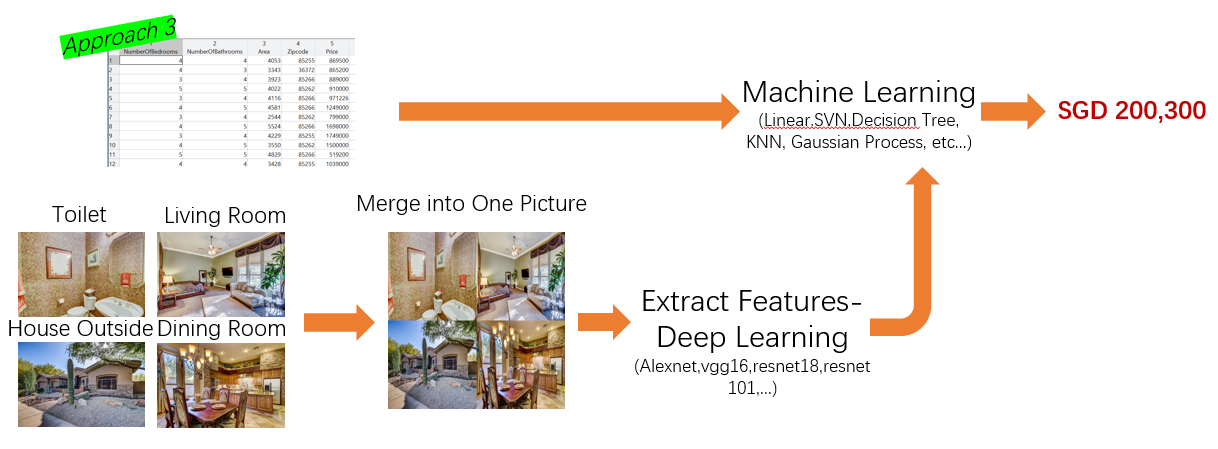

## **Highlights : **

- Technique to use machine learning for classification prediction and regression prediction

- Technique to use deep learning for classification prediction and regression prediction

- Compare different technique, familiar with how you can play around technique in Machine Learning and Deep Learning

## **Product Focus :**

- MATLAB

- Parallel Computing Toolbox

- Machine Learning and Statistics Toolbox

- Deep Learning Toolbox

**Written at 25 September 2019**

## Download Dataset

Download the dataset from git : [https://github.com/emanhamed/Houses-dataset](https://github.com/emanhamed/Houses-dataset)  

Citation for Dataset : *@article{ahmed2016house, title={House price estimation from visual and textual features}, author={Ahmed, Eman and Moustafa, Mohamed}, journal={arXiv preprint arXiv:1609.08399}, year={2016} }*

web("https://github.com/emanhamed/Houses-dataset")

you may use git to clone the data for the advantage of source control.

## Familiar with Dataset

In the dataset, we have two types of data inside the folder - "House Dataset".

Inside the folder : 

a) 2140 photo (It represents 535 sets of image, 1 set of image comprises bathrooms,bedrooms,frontal and kitchen.

b) a text file comprising the information of Number of Bedrooms, Number of bathrooms, Area, Zipcode, Price

### Image Dataset : Merge 4 images into one

first, let us merge 4 images (bathrooms,bedrooms,frontal and kicthen) into one to represent 1 set of data. 

House_Image_Datastore = imageDatastore("Houses-dataset-master\Houses Dataset");
House_Image_Datastore.ReadFcn = @customReadDatstoreImage;

currentFolder = pwd;
mkdir NewImage
cd NewImage

reset(House_Image_Datastore)
i=1;

while hasdata(House_Image_Datastore)
    T1 = read(House_Image_Datastore);
    T2 = read(House_Image_Datastore);
    T3 = read(House_Image_Datastore);
    T4 = read(House_Image_Datastore);
    Number = regexp(House_Image_Datastore.Files{i},'\d*','Match');
    imwrite([T1 T2;T3 T4],sprintf("Dataset%4i.png",str2double(Number{end})));
    i=i+4;
end
cd(currentFolder)

Visualize one of the merged image.

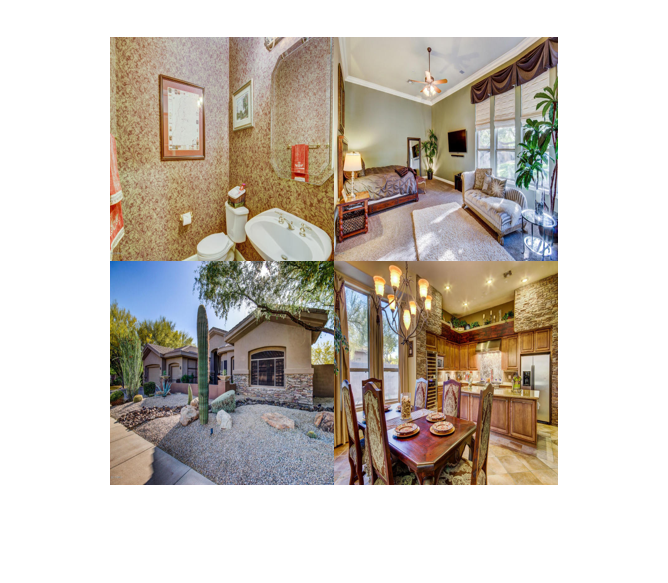

imshow("NewImage\Dataset   1.png")

## Text Dataset 

Data = importfile("Houses-dataset-master\Houses Dataset\HousesInfo.txt");
head(Data)

ans = 8×5 table
    NumberOfBedrooms    NumberOfBathrooms    Area    Zipcode      Price   
    ________________    _________________    ____    _______    __________
           4                    4            4053     85255      8.695e+05
           4                    3            3343     36372      8.652e+05
           3                    4            3923     85266       8.89e+05
           5                    5            4022     85262        9.1e+05
           3                    4            4116     85266     9.7123e+05
           4                    5            4581     85266      1.249e+06
           3                    4            2544     85262       7.99e+05
           4                    5            5524     85266      1.698e+06

## Solution 1 : Classification Prediction of House Price

open("classification_prediction_of_house_Price.mlx")

## Solution 2 : Regression Prediction of House Price

open("regression_prediction_of_house_Price.mlx")

## Extra Resources

1) You may refer to [https://www.mathworks.com/matlabcentral/fileexchange/71000-to-optimise-hyperparameter-of-ml-model-using-f1](https://www.mathworks.com/matlabcentral/fileexchange/71000-to-optimise-hyperparameter-of-ml-model-using-f1) on how to improve the accuracy.

2) Should remove outliers first before training any model (deep learning or machine learning) - This example didn't apply it.

## Supporting Function

%Resize the Image in the datastore

function data = customReadDatstoreImage(filename)
% code from default function: 
onState = warning('off', 'backtrace'); 
c = onCleanup(@() warning(onState)); 
data = imread(filename); % added lines: 
data = data(:,:,min(1:3, end)); 
data = imresize(data,[224 224]);
end